% RESOLUÇÃO COMPUTACIONAL DA LISTA EXTRA DE SS2

% EXERCÍCIO 1
% b)

### `Gráfico de Bode para `$H_1(j\omega)$

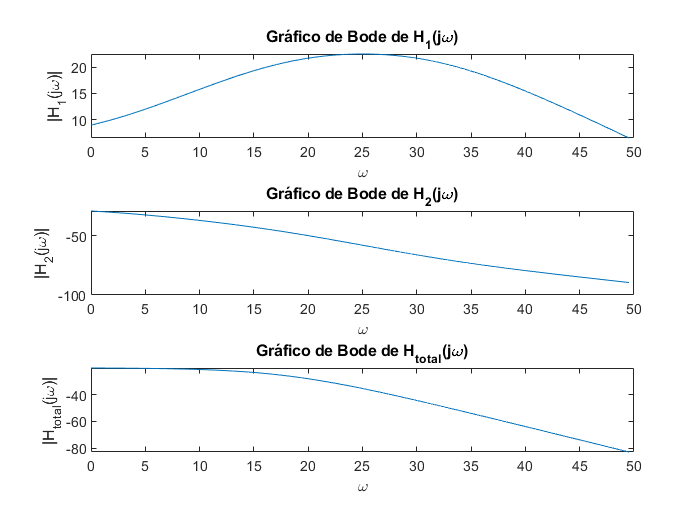

w = 1:0.01:300;
H1 = 640*(1i*w+1)./((1i*w+8).*(1i*w+40));
H2 = 0.01*(1i*w+40)./((1i*w+1).*(1i*w+8));
Htotal = 6.4 ./((1i*w+8).*(1i*w+8));

h = figure;
subplot(3,1,1); plot(20*log10(w), 20*log10(abs(H1)));
title('Gráfico de Bode de H_1(j\omega)');
xlabel('\omega');
ylabel('|H_1(j\omega)|');
subplot(3,1,2); plot(20*log10(w), 20*log10(abs(H2)));
title('Gráfico de Bode de H_2(j\omega)');
xlabel('\omega');
ylabel('|H_2(j\omega)|');
subplot(3,1,3); plot(20*log10(w), 20*log10(abs(Htotal)));
title('Gráfico de Bode de H_{total}(j\omega)');
xlabel('\omega');
ylabel('|H_{total}(j\omega)|');
% todos estão em escala dB

saveas(h, 'Ex1_b.jpg');